# Model Comparison with BIC

This tutorial demonstrates how to compare different models using the Bayesian Information Criterion (BIC). Using a simple simulation where we know the true model underlying the data, we can compare multiple models and determine the relative evidence in favor of each.

## Data Generation 

Here we are going to generate data y that is the sum of x1, the interaction between x1 and x2, and some noise

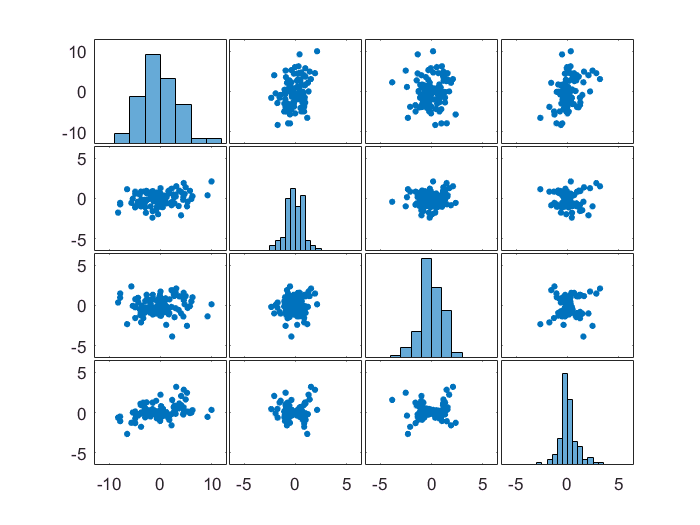

%first pick a random seed for reproducability
seed=randseed(1);
rng(seed);

%set parameter values and generate data
n = 100;
noise_scale_factor = 3; %some interesting values to try here include 3, 6, and 15
x1 = randn(n,1);
x2 = randn(n,1);
y = x1  + x1.*x2 + noise_scale_factor*randn(n,1);

%plot data
plotmatrix([y x1 x2 x1.*x2])

## Model Specification

Here we are creating a set of nested models including a constant term, x1, x2, and their interaction

% constant model
X0 = ones(n,1);

% model only including x1
X1 = [X0 x1];

% model only including x2
X2 = [X0 x2];

% model including both x1 and x2
X3 = [X0 x1 x2];

% model including just the interaction
X4 = [X0 x1.*x2];

% model including x1 and the interaction of x1 and x2
X5 = [X0 x1 x1.*x2];

% model including x1 and the interaction of x1 and x2
X6 = [X0 x2 x1.*x2];

% model including x1, x2 and their interaction
X7 = [X0 x1 x2 x1.*x2];


## Fit GLMs

We can use fitglm to create GeneralizedLinearModel objects, which will also allow us to easily compute BIC

% constant model
GLM0 = fitglm(X0,y,'Intercept',false);

% model only including x1
GLM1 = fitglm(X1,y,'Intercept',false);

% model only including x2
GLM2 = fitglm(X2,y,'Intercept',false);

% model including both x1 and x2
GLM3 = fitglm(X3,y,'Intercept',false);

% model including just the interaction
GLM4 = fitglm(X4,y,'Intercept',false);

% model including x1 and the interaction of x1 and x2
GLM5 = fitglm(X5,y,'Intercept',false);

% model including x2 and the interaction of x1 and x2
GLM6 = fitglm(X6,y,'Intercept',false);

% model including x1, x2 and their interaction
GLM7 = fitglm(X7,y,'Intercept',false);



## Compute BIC for each model

Eq 1: BIC = -2$ln\left(\hat{L} \right)$ + $k\ln \left(n\right)$, where 

$\hat{L}$ is the maximized value of the likelihood function

*k *is the number of free parameters in the model

*n *is the number of data points

This is also known as the [Swarz Criterion](http://projecteuclid.org/download/pdf_1/euclid.aos/1176344136)

See GeneralizedLinearModel.ModelCriterion

References:

Schwarz, G. (1978). Estimating the dimension of a model. *The annals of statistics*, *6*(2), 461-464.

% constant model
BIC0 = GLM0.ModelCriterion.BIC;

% model only including x1
BIC1 = GLM1.ModelCriterion.BIC;

% model only including x2
BIC2 = GLM2.ModelCriterion.BIC;

% model including both x1 and x2
BIC3 = GLM3.ModelCriterion.BIC;

% model including just the interaction
BIC4 = GLM4.ModelCriterion.BIC;

% model including x1 and the interaction of x1 and x2
BIC5 = GLM5.ModelCriterion.BIC;

% model including x1 and the interaction of x1 and x2
BIC6 = GLM6.ModelCriterion.BIC;

% model including x1, x2 and their interaction
BIC7 = GLM7.ModelCriterion.BIC;


## Compute $\Delta$BIC, wBIC, and Bayes Factors

From the raw BIC values, we can compute their relative differences ($\Delta$BIC) and transform them to reflect relative model likelihoods (wBIC), all of which can be used to approximate [Bayes Factors](http://xyala.cap.ed.ac.uk/teaching/tutorials/phylogenetics/Bayesian_Workshop/PDFs/Kass%20and%20Raftery%201995.pdf) (BF)

Formulae for computing thse values and an example of using this method can be found [here](https://www.researchgate.net/profile/Simon_Farrell/publication/8588301_AIC_model_selection_using_Akaike_weights/links/53fc51540cf22f21c2f3c376.pdf)

Eq 2: $\Delta {\text{BIC}}_i ={\text{BIC}}_i −\min \text{ }\left(\text{BIC}\right)$ 

Eq 3: $w_i BIC=$$\frac{e^{−\frac{1}{2}\Delta_i \text{BIC}} }{{\sum_{k=1}^K e}^{−\frac{1}{2}\Delta_k BIC} }$  

Eq 4: $B_{10} =\text{ }$$e^{−\frac{1}{2}\left({\text{BIC}}_1 −{\text{BIC}}_0 \right)}$ = $\frac{w_1 \text{BIC}}{w_0 \text{BIC}}$

References:

Kass, R. E., & Raftery, A. E. (1995). Bayes factors. *Journal of the american statistical association*, *90*(430), 773-795.

Wagenmakers, E. J., & Farrell, S. (2004). AIC model selection using Akaike weights. *Psychonomic bulletin & review*, *11*(1), 192-196.

% model names
model={'Constant' 'x1' 'x2' 'x1 + x2' 'x1 * x2' 'x1 + x1 * x2' 'x2 + x1 * x2' 'x1 + x2 + x1 * x2'}';

% make single variable with all BIC values
BIC= [BIC0 BIC1 BIC2 BIC3 BIC4 BIC5 BIC6 BIC7]';

% here we find the model with the lowest BIC and compute the difference in BIC
dBIC = BIC-min(BIC);

% compute BIC weights
wBIC = exp(-.5*dBIC)/sum(exp(-.5*dBIC));

% convert to Bayes Factors of this model vs. this model
B = exp(.5*dBIC);

% display results in table
tbl=table(model,BIC,dBIC,wBIC,B);
display(tbl)

tbl =            model            BIC       dBIC        wBIC         B   
    ___________________    ______    ______    __________    ______

    'Constant'              543.6    13.662    0.00092579    926.14
    'x1'                   538.53    8.5889      0.011698    73.293
    'x2'                   548.06     18.12    9.9658e-05    8603.6
    'x1 + x2'              543.13     13.19     0.0011721    731.51
    'x1 * x2'              536.18    6.2434      0.037797    22.685
    'x1 + x1 * x2'         529.94         0       0.85741         1
    'x2 + x1 * x2'         540.75    10.817     0.0038401    223.28
    'x1 + x2 + x1 * x2'    534.51    4.5747      0.087057    9.8489



%note that ratios of wBIC values are equivalent to approximations of the Bayes Factor

## Interpreting Bayes Factors and $\Delta$BIC

Kass and Raftery 1995 provides the following rule of thumb for interpretation: